CS 567 (HW5)

Sparsh Agarwal

9075905142

Q1

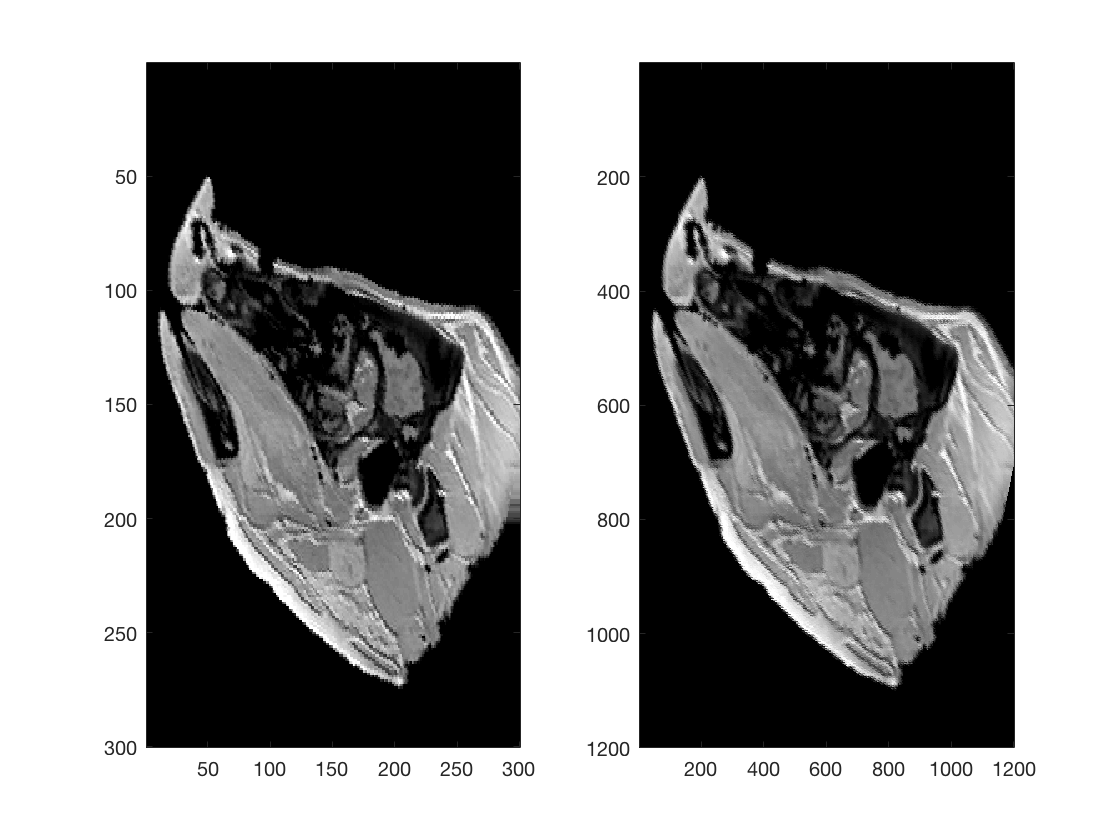

% figure
img=PorkyPig;
img=round(img/4.0);
% colormap(gray)
% image(img)

% Bilinear stuff
newimg=zeros(1200,1200);
for i=1:1200
for j=1:1200
si=round(i/4.0);
sj=round(j/4.0);
if si > 0 && si < 300 && sj > 0 && sj < 300
rho=img(si,sj);
newimg(i,j)=rho;
end
end
end
% figure
% colormap(gray)
% image(newimg)

angle=-20;
rotmat=zeros(2,2);
rotmat(1,1)=cos(angle*pi/180);
rotmat(1,2)=-sin(angle*pi/180);
rotmat(2,1)=sin(angle*pi/180);
rotmat(2,2)=cos(angle*pi/180);
rotmat=transpose(rotmat);
shift=zeros(2,1);
shift(1,1)= 600;
shift(2,1)= 600;

% oldpix=zeros(2,1);
newpix=zeros(2,1);
rhoMat=zeros(2,2);

for i=1:1200
for j=1:1200
newpix(1,1)=i;
newpix(2,1)=j;
oldpix=round(rotmat*(newpix-shift)+shift);
pivot00i=floor(oldpix(1,1)/(1200/300));
pivot00j=floor(oldpix(2,1)/(1200/300));
if pivot00i > 1 && pivot00i < 300 && pivot00j > 1 && pivot00j < 300 
rho00=img(pivot00i,pivot00j);
rho01=img(pivot00i,(pivot00j+1));
rho10=img((pivot00i+1),pivot00j);
rho11=img((pivot00i+1),(pivot00j+1));
rhoMat(1,1)=rho00;
rhoMat(1,2)=rho10;
rhoMat(2,1)=rho01;
rhoMat(2,2)=rho11;
denx=mod(i,(1200/300));
deny=mod(j,(1200/300));
leftVect=([(1-deny/(1200/300)),(deny/(1200/300))]);
rightVect=transpose([(1-denx/(1200/300)),(denx/(1200/300))]);
newimg(i,j)=leftVect*rhoMat*rightVect;
end
end
end

% NN stuff
angle=-20;
rotmat=zeros(2,2);
rotmat(1,1)=cos(angle*pi/180);
rotmat(1,2)=-sin(angle*pi/180);
rotmat(2,1)=sin(angle*pi/180);
rotmat(2,2)=cos(angle*pi/180);
rotmat=transpose(rotmat);
shift=zeros(2,1);
shift(1,1)= 150;
shift(2,1)= 150;

oldpix=zeros(2,1);
newpix=zeros(2,1);
rotimg=zeros(300,300);

rho=0;
for i=1:300
    for j=1:300
        newpix(1,1)=i;
        newpix(2,1)=j;
	oldpix=round(rotmat*(newpix-shift)+shift);
        if (oldpix(1,1) > 0) && (oldpix(1,1) < 300) && (oldpix(2,1) > 0) && (oldpix(2,1) < 300)
            rho=img(oldpix(1,1),oldpix(2,1));
        end
	rotimg(i,j)=rho;
    end
end

% Result plot
figure
subplot(1,2,1)
colormap(gray)
image(rotimg)
subplot(1,2,2)
colormap(gray)
image(newimg)

Q2.

clear;
file_path =  '/Users/sparshagarwal/OneDrive/Spring 2018/CS 567/AMIP_II_CD/LessonData/9_Registration/';
ctimg= double(imread(sprintf('%s/CT.jpg', file_path)));
t1img=double(imread(sprintf('%sT1.jpg', file_path)));

hist_variable=zeros(1,256);
for i=1:388
    for j=1:388
        hist_variable(1,ctimg(i,j)+1) = hist_variable(1,ctimg(i,j)+1) + 1;
    end
end

HCT = 0;
for i=1:256
    if hist_variable(1,i)~=0
        p = hist_variable(1,i)./(size(ctimg,1)*size(ctimg,2));
        HCT = HCT + -1*p*log(p);
    end
end

HCT

HCT = 2.8000


hist_variable=zeros(1,256);
for i=1:388
    for j=1:388
        hist_variable(1,t1img(i,j)+1) = hist_variable(1,t1img(i,j)+1) + 1;
    end
end

HT1 = 0;
for i=1:256
    if hist_variable(1,i)~=0
        p = hist_variable(1,i)./(size(t1img,1)*size(t1img,2));
        HT1 = HT1 + -1*p*log(p);
    end
end

HT1

HT1 = 2.0022

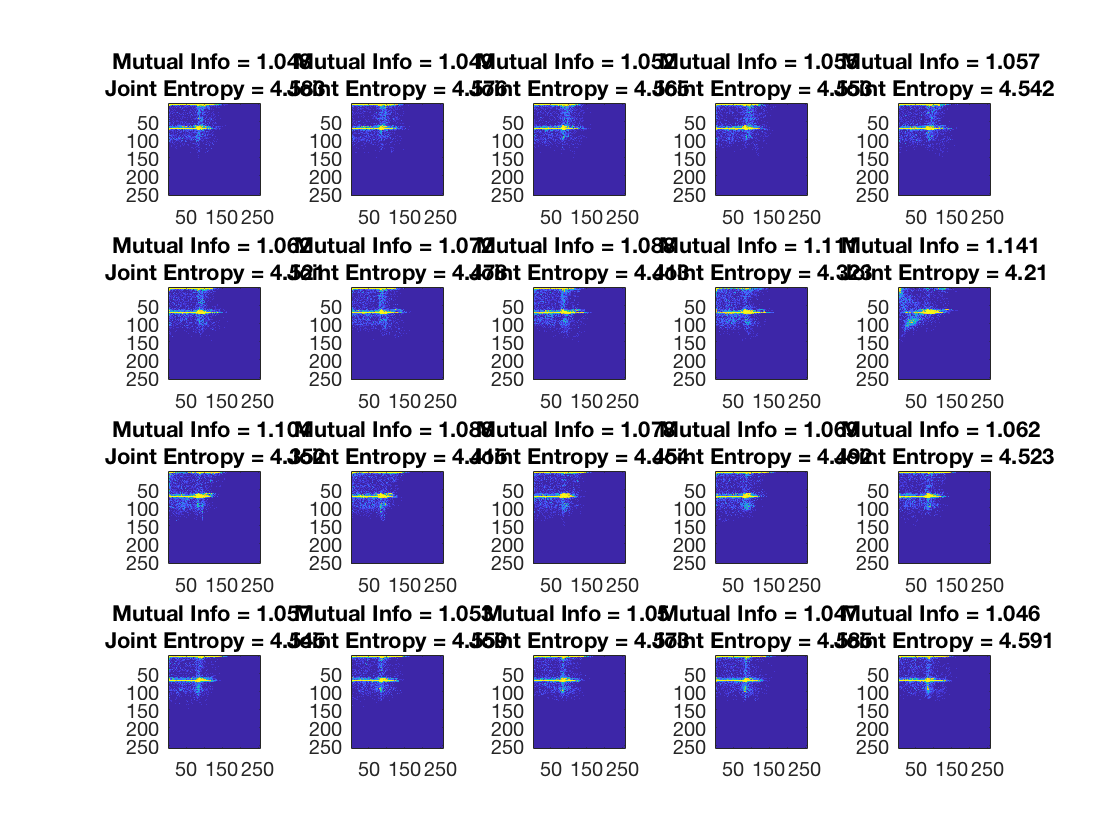

hist_variable=zeros(1,256);
figure
for angle=-90:10:100
    rotimg=zeros(388,388);
    rotmat=zeros(2,2);
    rotmat(1,1)=cos(angle*pi/180);
    rotmat(1,2)=-sin(angle*pi/180);
    rotmat(2,1)=sin(angle*pi/180);
    rotmat(2,2)=cos(angle*pi/180);
    invrotmat=transpose(rotmat);
    oldpix=zeros(2,1);
    newpix=zeros(2,1);
    shift=transpose([194,194]);
    for i=1:388
        for j=1:388
            newpix(1,1)=i;
            newpix(2,1)=j;
            oldpix=round((invrotmat*(newpix-shift))+shift);
            if (oldpix(1,1) > 0) && (oldpix(1,1) < 388) && (oldpix(2,1) > 0) && (oldpix(2,1) < 388)
                rotimg(i,j)=t1img(oldpix(1,1),oldpix(2,1));
            end
        end
    end
    hist_variable=zeros(256,256);
    for i=1:388
        for j=1:388
            rho1=ctimg(i,j)+1;
            rho2=rotimg(i,j)+1;
            hist_variable(rho1,rho2)=hist_variable(rho1,rho2)+1;
        end
    end
    Hjoint = 0;
    for i=1:256
        for j=1:256
            if hist_variable(i,j)~=0
                p = hist_variable(i,j)./(size(ctimg,1)*size(ctimg,2));
                Hjoint = Hjoint + -1*p*log(p);
            end
        end
    end
    mutinfo = (HCT+HT1)./Hjoint;
    m = 4;
    s = 4;
    hist_variable = 63*1./(1+exp(-1*(hist_variable-m)/s));
    subplot(4, 5, (angle/10)+10)
    imagesc(hist_variable)
    title(sprintf('Mutual Info = %.4g \n Joint Entropy = %.4g ', mutinfo, Hjoint));
    axis('square')
end

Q3.

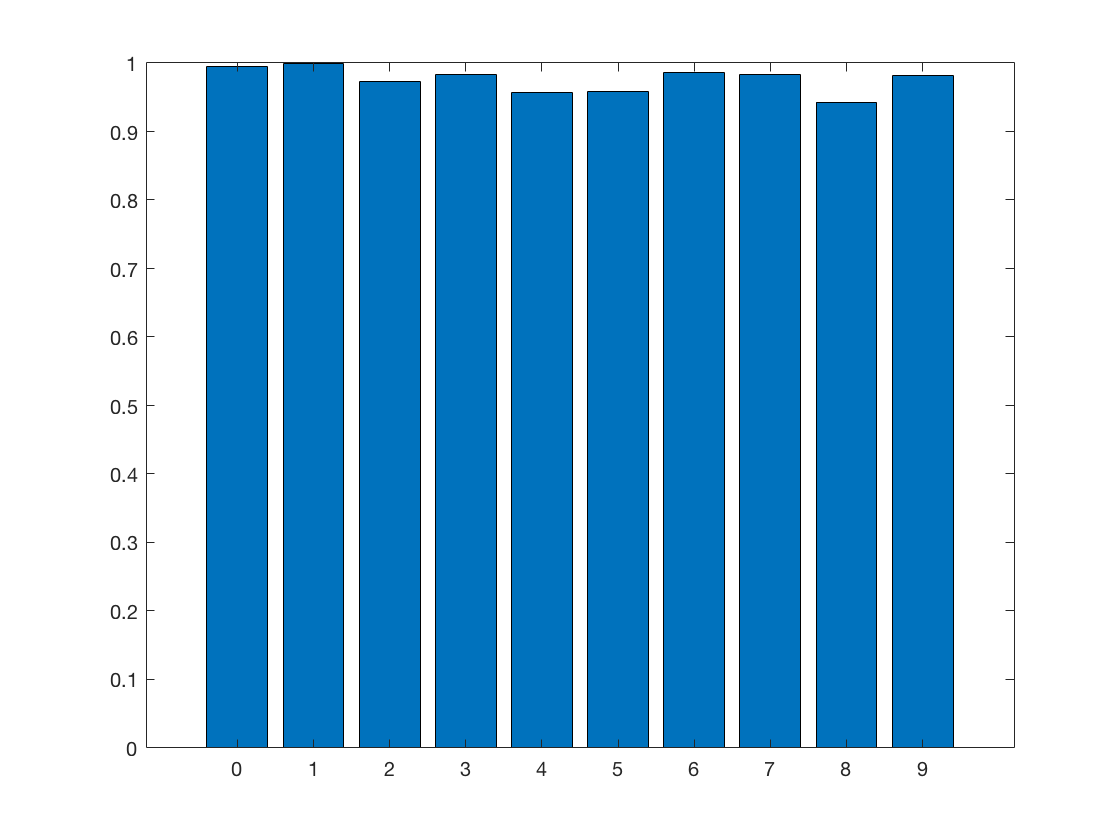

% KNN illustration

test = load('/Users/sparshagarwal/OneDrive/Spring 2018/CS 567/Medical-Imaging/HW 5/train.txt', '-ascii');
train = load('/Users/sparshagarwal/OneDrive/Spring 2018/CS 567/Medical-Imaging/HW 5/train.txt', '-ascii');

% train(1,1) 
% imagesc(reshape(train(1,2:end), 16,16)')
train_feat(:,:) = train(:,2:257);
train_labels(:) = train(:,1);
test_feat(:,:) = test(:,2:257);
test_labels(:) = test(:,1);    


k = 5;

npairs = length(test_labels);
ntrain = size(train_feat, 1);

pred = zeros(npairs,1);

for i=1:npairs
    dist = sqrt(sum((ones(ntrain,1)*test_feat(i,:)-train_feat).^2, 2));
    [reord, ord] = sort(dist);
    knn=train_labels(ord(1:k));
    for j = 1:10
        p_g(j) = mean(knn == j-1);
    end
    [sorted_prob,digit] = sort(p_g,'descend');
    pred(i) = digit(1,1)-1;
end
match = test_labels' == pred;
for i = 1:10
    accuracy(i) = mean(match(test_labels == i-1));
end

figure
bar(0:9,accuracy)